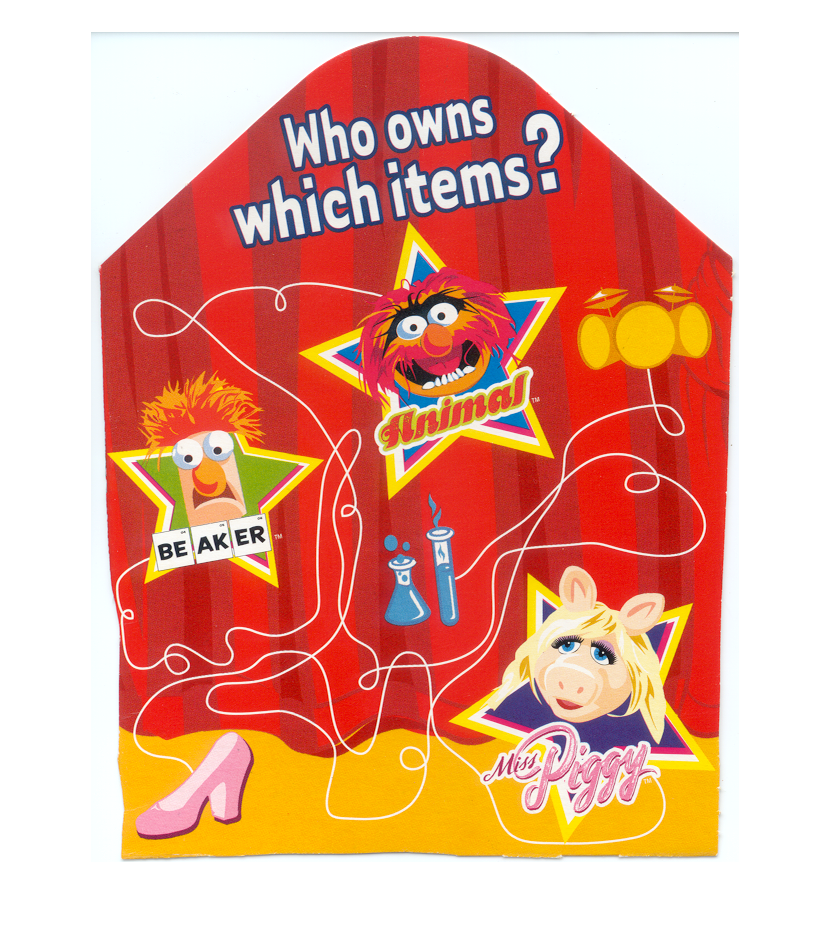

image = imread('sesame.tif');
imshow(image);

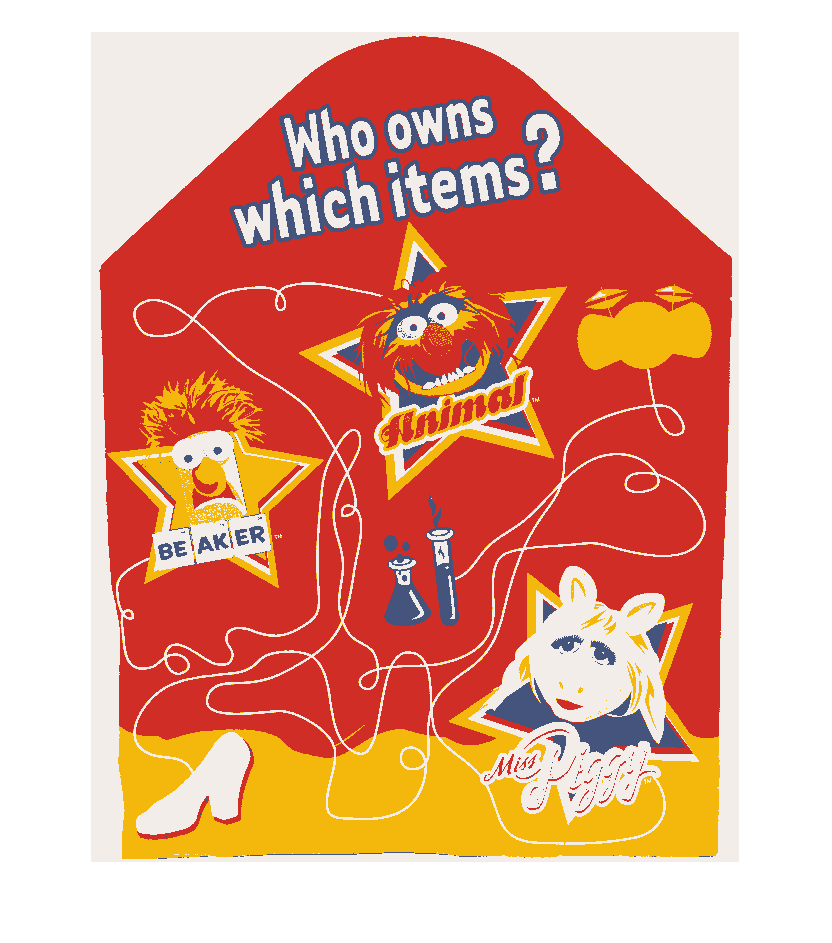

quantisedImage = kmeansImage(image, 4);
imshow(quantisedImage);

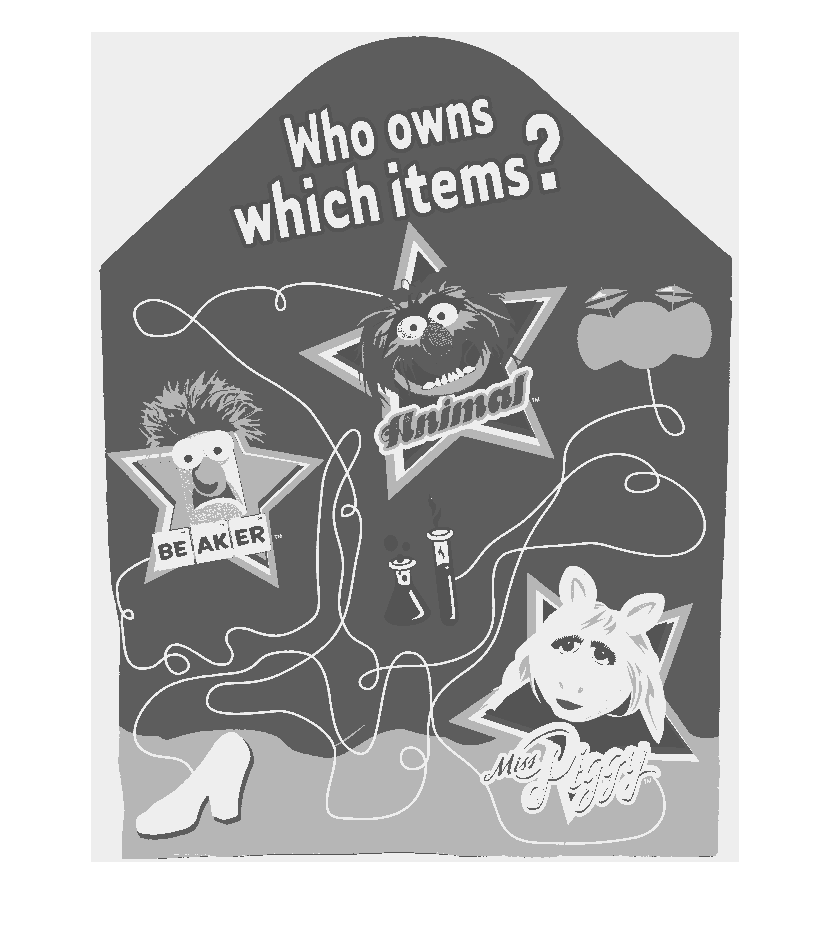

grayImage = rgb2gray(quantisedImage);
imshow(grayImage);

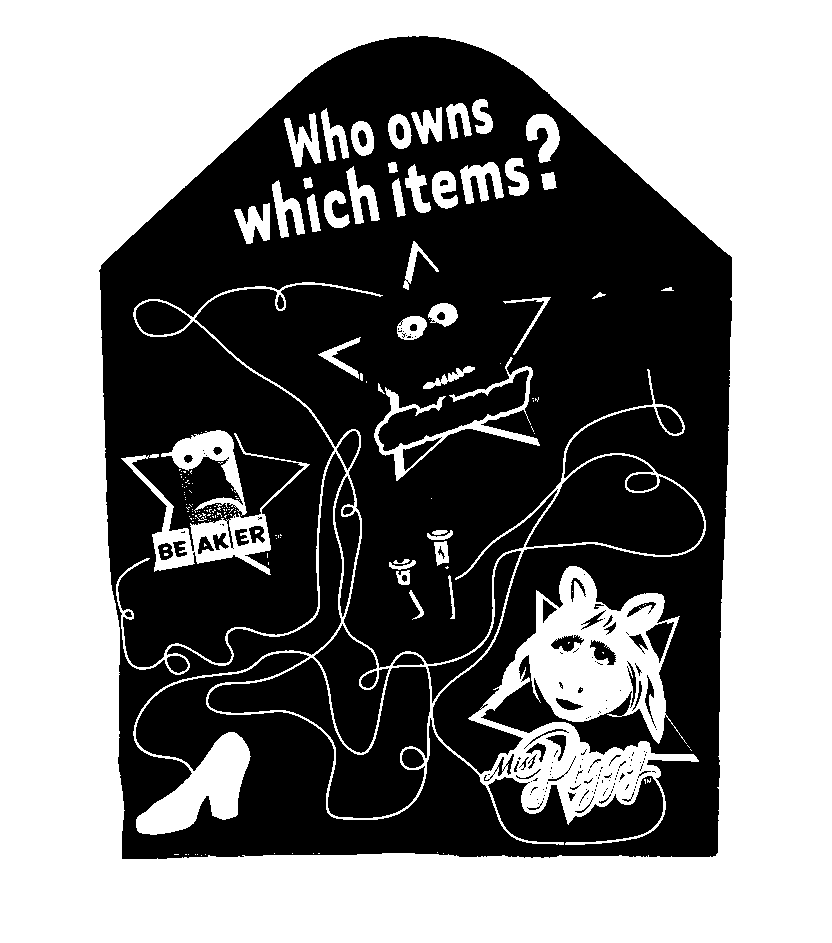

bw = imbinarize(grayImage, 0.8);
imshow(bw);

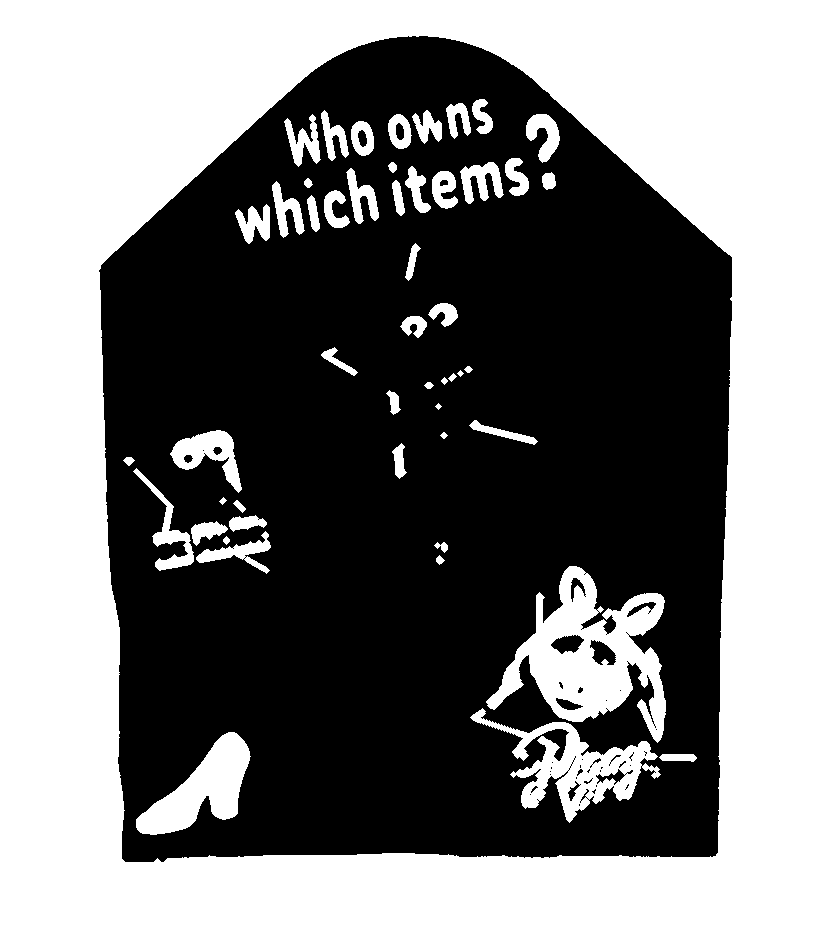

linesRemoved = imopen(bw, strel('diamond', 3));
imshow(linesRemoved);

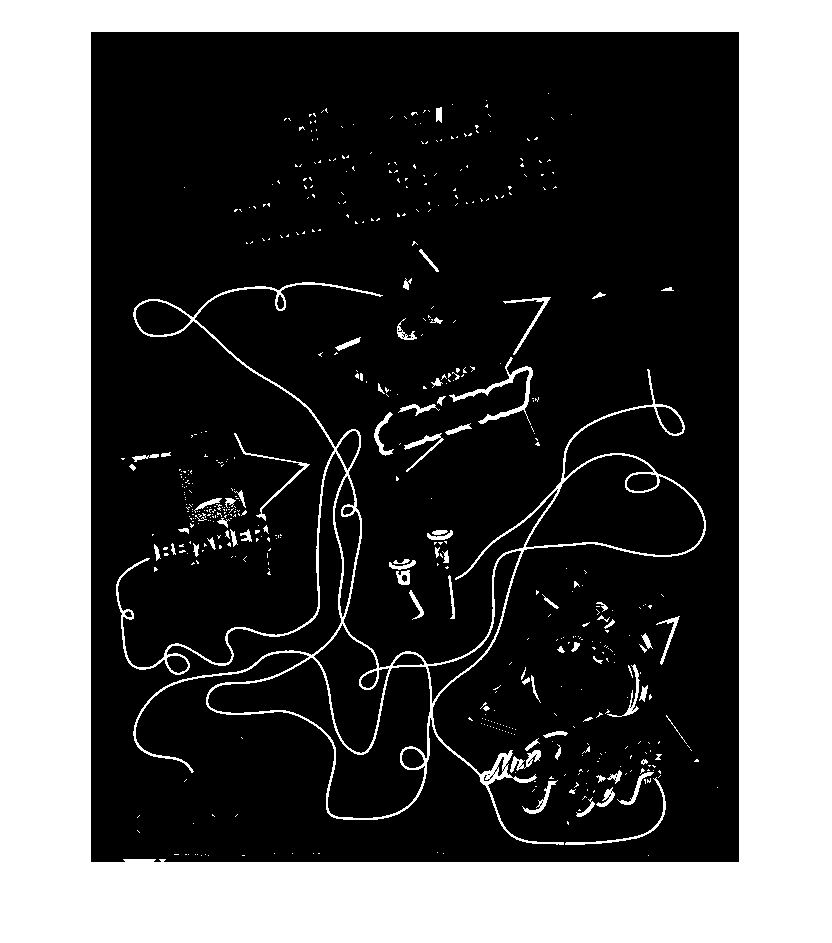

lines = linesRemoved ~= bw;
imshow(lines);

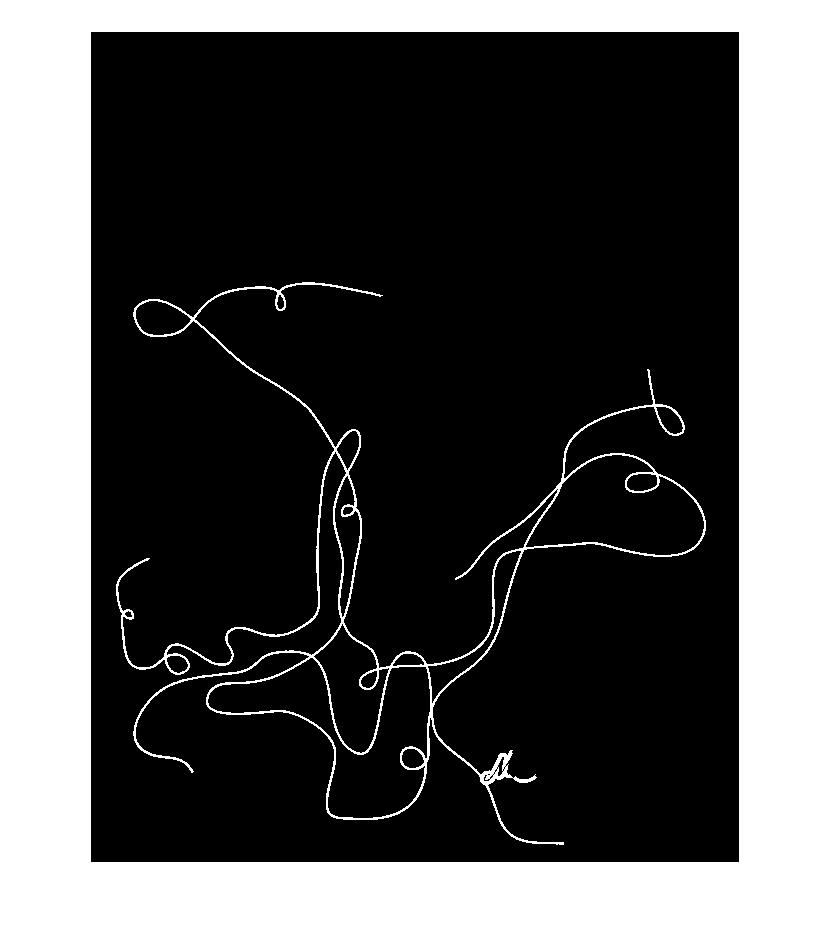

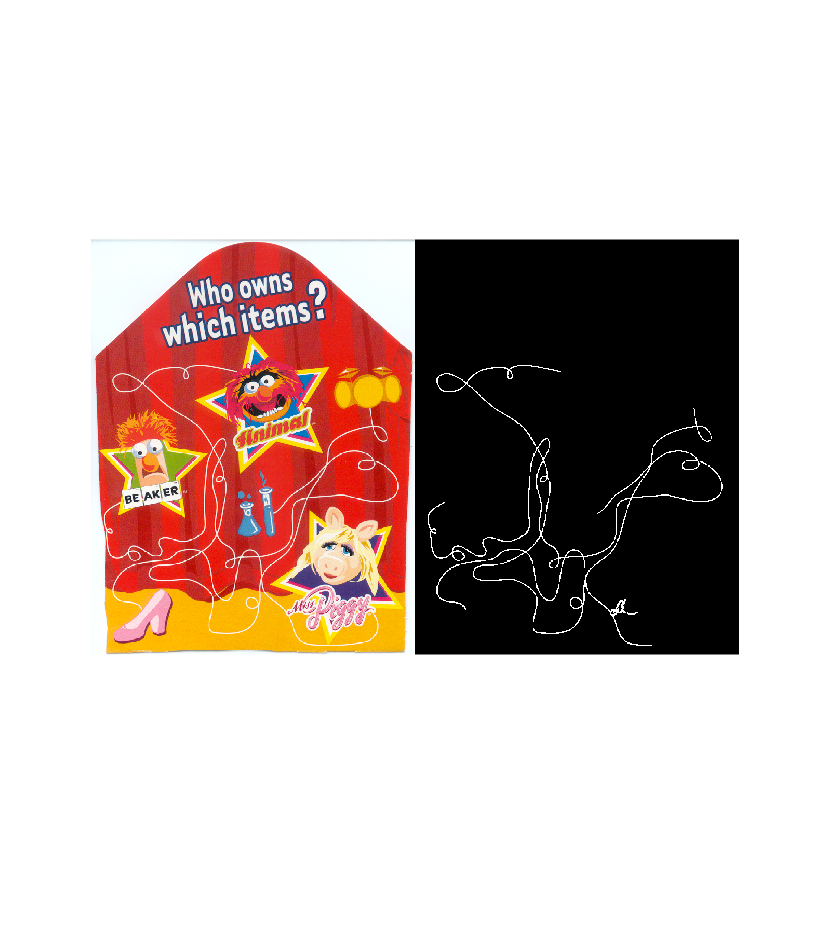

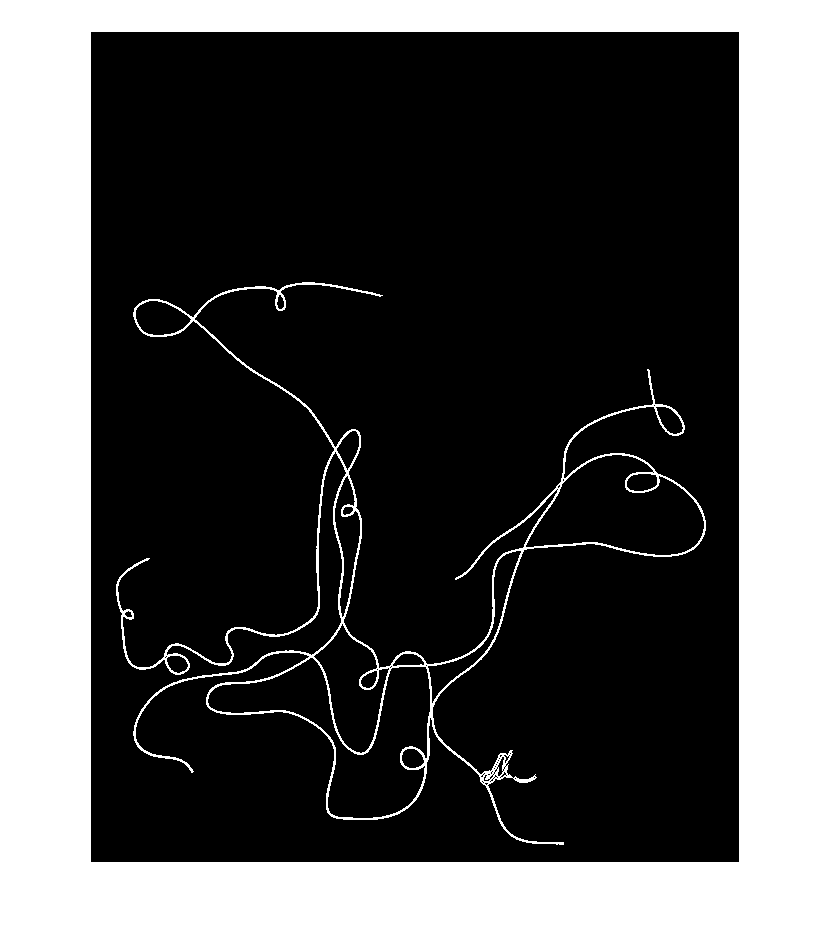

justLine = zeros(size(lines));
stats = regionprops('table', lines, 'Area', 'PixelIdxList');
[sortedComponentAreas, sortingIndex] = sort(stats.Area, 'descend');
justLine(stats.PixelIdxList{sortingIndex(1)}) = 1;
justLine = justLine == 1;
imshow(justLine);

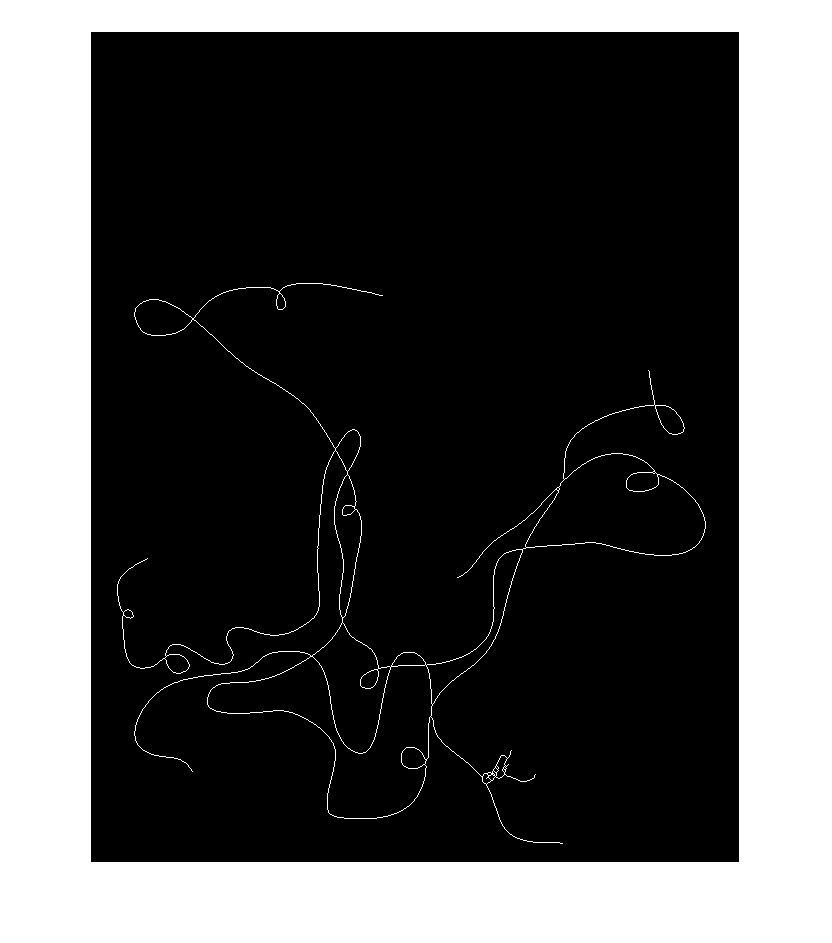

skeleton = bwskel(justLine);
imshow(skeleton);

endPoints = bwmorph(skeleton, 'endpoints');
[row, col] = find(endPoints);

tracker = LineTracker(skeleton);

for index = 1:size(row, 1)
    tracker.trackFrom([row(index) col(index)]);
    
    figure();
    imshow(image);
    hold on; 
    scatter(tracker.theTrack(:,2), tracker.theTrack(:,1), 2, '*');
    scatter(col(index), row(index), '*');
    hold off;
end

Index in position 2 is invalid. Array indices must be positive integers or logical values.

Error in LineTracker/handleIntersectionCase (line 125)
            if(self.theBW(searchPos(1), searchPos(2)) && ...

Error in LineTracker/trackNextPoint (line 63)
                self.handleIntersectionCase